# Solve Max-Cut Problem Using QAOA

This example shows how to use the quantum approximate optimization algorithm (QAOA) to solve max-cut problems. The max-cut problem is a graph partitioning problem whose objective is to create two subsets of vertices that maximize the number of edges between the two groups. In this example, you first solve a max-cut problem classically by considering all graph partitions and then solve it using QAOA.

## Set Up Max-Cut Problem

Generally, the max-cut problem can be expressed as

    $\max \;\sum_{i,j=1}^N w_{\textrm{ij}} x_i \left(1-x_j \right)$,

where *N* is the number of nodes in the graph, $x_i$ denotes which node subset node $i$ is in using 0 or 1, and $w_{\textrm{ij}}$ is the weight of the edge between nodes $i$ and $j$. 

Create and plot a four-node graph where all edges have unit weight 1.

s = [1 1 2 3];
t = [2 4 3 4];
weights = [1 1 1 1];
G = graph(s,t,weights);
plot(G)

Using the max-cut expression, the objective function to maximize for this graph is:

    
$$\begin{array}{l}
f=\sum_{i,j=1}^4 w_{\textrm{ij}} x_i \left(1-x_j \right)\\
\;\;\;=\left(x_1 \left(1-x_2 \right)+x_2 \left(1-x_1 \right)\right)+\left(x_1 \left(1-x_4 \right)+x_4 \left(1-x_1 \right)\right)\\
\;\;\;\;\;\;\;\;\;+\left(x_2 \left(1-x_3 \right)+x_3 \left(1-x_2 \right)\right)+\left(x_3 \left(1-x_4 \right)+x_4 \left(1-x_3 \right)\right)
\end{array}$$


## Solve Using Classical Approach

A graph with $N$ nodes has $2^N$ possible solutions, or ways to partition the nodes into two subsets. For the four-node example, there are $2^4$, or 16, possible solutions. Use the objective function to calculate the solution for each partition and list them in a table. Each row of the `allSols` table represents a possible partition, and the table variable `f` represents the objective value for the corresponding partition, or how many edges are between the subsets.

x = double(dec2bin(0:15)=='1');
[i,j] = findedge(G);
allFval = sum(x(:,i) .* (1-x(:,j)),2) + sum(x(:,j) .* (1-x(:,i)),2);
allSols = array2table([x,allFval],VariableNames=["x1","x2","x3","x4","f"]);
allSols = sortrows(allSols,"f","descend")

Two solutions maximize the number of edges between the two subsets of nodes. In both solutions, the graph is partitioned so that nodes $x_1$ and $x_3$ are in one subset and nodes $x_2$ and $x_4$ are in the other subset. These partitions result in four edges between the two groups.

## Solve Using QAOA Approach

QAOA is a quantum-classical hybrid approach to solving optimization problems. In this hybrid approach, a quantum circuit represents potential solutions to the problem, and a classical optimizer iteratively adjusts the angles in the circuit to improve the quality of the solution. 

This section shows two ways to solve the max-cut problem using the QAOA approach, by using QAOA functions and by manually setting up and measuring a QAOA circuit.

### Use QAOA Functions

Convert the graph `G` into a Quadratic Unconstrained Binary Optimization (QUBO) problem. Then solve the QUBO problem using QAOA.

qprob = maxcut2qubo(G);
result = solve(qprob,Algorithm=qaoa)

Examine the results. Because `solve` minimizes the objective function, the negation of the `BestFunctionValue` property is the maximum number of cuts. The `BestX` property defines a partition that maximizes the number of cuts. In this case, partitioning nodes 1 and 3 into one group and nodes 2 and 4 into another group yields the maximum number of four edge cuts.

result.BestFunctionValue
result.BestX

### Set Up QAOA Manually

You can also solve the max-cut problem using QAOA manually. For this problem, the manual QAOA approach has steps for initialization, optimization, and termination.

Initialization

- Create a QAOA circuit that encodes the max-cut problem. This circuit is composed of Hadamard and rotation gates that are parameterized by the set of angles $\theta$.

- Define a set of initial angles $\theta_0$.

Optimization

- Measure the QAOA circuit.

- Calculate the expected objective value from the measurements.

- Update the angles that are used in the QAOA circuit if the termination criteria is not met.

Termination

- Measure the QAOA circuit at the set of angles $\theta$ that satisfy the termination criteria.

- Return the final values.

This `expectedObjectiveValue` function implements the algorithm steps for the four-node example.

function expVal = expectedObjectiveValue(theta,G,numLayers,numShots)
    % Create and simulate the QAOA circuit.
    circuit = qaoaCircuit(G,theta,numLayers);
    sv = simulate(circuit);
    
    % Measure circuit numShots times.
    meas = randsample(sv,numShots);
    
    % Convert measured state to double matrix, assuming all entries are 0 or 1.
    x = double(char(meas.MeasuredStates) == '1');

    % Calculate number of cuts for each measured state.
    [i,j] = findedge(G);
    numCuts = sum(x(:,i) .* (1-x(:,j)),2) + sum(x(:,j) .* (1-x(:,i)),2);

    % Calculate expected number of cuts.
    expVal = sum(meas.Counts.*numCuts)/numShots;
end

**QAOA Circuit**

The QAOA circuit for the max-cut problem uses a set of Hadamard gates, which place all gates in an equal superposition, and layers of cost and mixer gates, as seen in the circuit from [2]. The cost gates encode a Hamiltonian for the objective function of the optimization problem. The mixer gates, which allow the quantum state to transition between energy states, encode a simple Hamiltonian whose maximal state is ${\left∣++++\right\rangle}$. This maximal state is the equal superposition state generated by the initial Hadamard gates and the initial QAOA state.

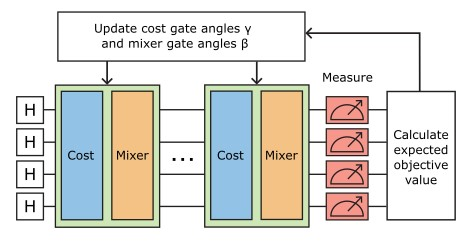

Create the QAOA circuit for one layer of the max-cut problem using the `qaoaCircuit` helper function. Here, `gamma` and `beta` define the angle of the cost gate and the angle of the mixer gate, respectively. To view the code for this helper function, see Helper Function.

gamma = 1;
beta = 3;
circuit = qaoaCircuit(G,[gamma;beta],1);
plot(circuit)

This circuit has four qubits, one for each node in the graph. Four Hadamard gates place all the qubits in an equal superposition and are followed by cost gates, composed of RZZ gates, and mixer gates, composed of RX gates. Each RZZ gate encodes an edge relationship in the original graph. 

In general, the alternating cost and mixer gates approximately solve the problem because QAOA is a discretized example of adiabatic quantum computation (AQC), as described in [1] and [2]. 

AQC uses a quantum system that combines a mixer Hamiltonian $H_M$, which represents an energy state that is easy to prepare, and a cost Hamiltonian $H_C$, which represents the energy state of the problem of interest. The adiabatic theorem states that if a quantum system starts in the given energy state of $H_M$, then it will remain in that state while $H_M$ is evolved to $H_C$, given that the change occurs at a sufficiently slow rate.

The Hamiltonian combination for the max-cut problem is

    $H\left(t\right)=\frac{t}{T}H_C +\left(1-\frac{t}{T}\right)H_M$,

where $T$ is the total run time of the system. The solution to the Schrödinger equation for this circuit can be written using the Trotter-Suzuki approximation as a series of multiplications of cost and mixer gates. 

#### Simulate Iterations of Max-Cut

Use `surrogateopt` (Global Optimization Toolbox) with the objective function to maximize the expected objective value. In this example, use two layers of cost-mixer gates and sample the circuit 1000 times each time the optimizer calculates the expected objective value. `surrogateopt` calculates a global minimum, so the negation of the expected objective value is minimized. Set the maximum number of objective function evaluations to 100. 

numLayers = 2;
numShots = 1000;
objFcn = @(theta) - expectedObjectiveValue(theta,G,numLayers,numShots);
bound = repmat(pi,2*numLayers,1);
x0Theta = rand(2,numLayers);
options = optimoptions("surrogateopt",InitialPoints=x0Theta,MaxFunctionEvaluations=100);
[angles,bestfval] = surrogateopt(objFcn,-bound,bound,[],[],[],[],[],options)

The best function value is approximately 4. In other words, the maximum number of edges between two subsets of nodes is 4.

Construct the quantum circuit using the optimized angles, and simulate the circuit to see the expected probability distribution over qubit states. The `0101` and `1010` states appear with the highest probabilities, which were the two solutions found when calculating the expected values classically.

optimizedCircuit = qaoaCircuit(G,angles,numLayers);
sv = simulate(optimizedCircuit);
histogram(sv)

#### Run Final Iteration on QPU

Connect to an IonQ device using `quantum.backend.QuantumDeviceAWS`. Specify the region of the device and path to a bucket to store results.

reg = "us-east-1";
bucketPath = "s3://amazon-braket-mathworks/doc-examples";
device = quantum.backend.QuantumDeviceAWS("Aria 1",S3Path=bucketPath,Region=reg)

Create a task to run the circuit with optimized angles on the QPU. Specify the number of shots as 1000.

task = run(optimizedCircuit,device,NumShots=1000);
wait(task)

Fetch the results and plot a histogram of the states.

results = fetchOutput(task);
histogram(results)

The states `0101` and `1010` appear again as the states with the highest probabilities, so the QPU results agree with the local simulation of the circuit.

## Helper Function

This code defines the `qaoaCircuit` helper function.

function circuit = qaoaCircuit(G,params,r) 
    params = reshape(params,[2 r]);
    N = numnodes(G);
    edges = G.Edges.EndNodes;
    target1 = edges(:,1);
    target2 = edges(:,2);
    
    gates = [];
    for ii = 1:r
        % Include a cost gate with the specified gamma angle.
        gates = [gates; rzzGate(target1,target2,params(1,ii))];
        % Include a mixer gate with the specified beta angle.
        gates = [gates; rxGate(1:N,2*params(2,ii))];        
    end
    circuit = quantumCircuit([hGate(1:N);gates]);
end

## References

[1]  J., Abhijith, Adetokunbo Adedoyin, John Ambrosiano, Petr Anisimov,  William Casper, Gopinath Chennupati, Carleton Coffrin, et al. “Quantum  Algorithm Implementations for Beginners.” *ACM Transactions on Quantum Computing* 3, no. 4 (December 31, 2022): 1–92. [https://doi.org/10.1145/3517340](https://doi.org/10.1145/3517340).

[2] Zhou, Leo, Sheng-Tao Wang, Soonwon Choi, Hannes Pichler, and Mikhail D.  Lukin. “Quantum Approximate Optimization Algorithm: Performance,  Mechanism, and Implementation on Near-Term Devices.” *Physical Review X* 10, no. 2 (June 24, 2020): 021067. [https://doi.org/10.1103/PhysRevX.10.021067](https://doi.org/10.1103/PhysRevX.10.021067).

*Copyright 2024 The MathWorks, Inc.*